Labo A - Principes van digitale signaalverwerking

2.4 Datasets:

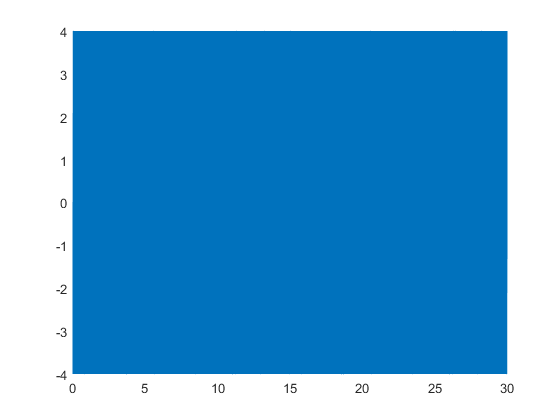

r = 4;
f = 440;
fs = 8192;
Ts = 1/fs;
t = (0:Ts:30);

a = r * sin(2 * pi * f * t);
plot(t, a)

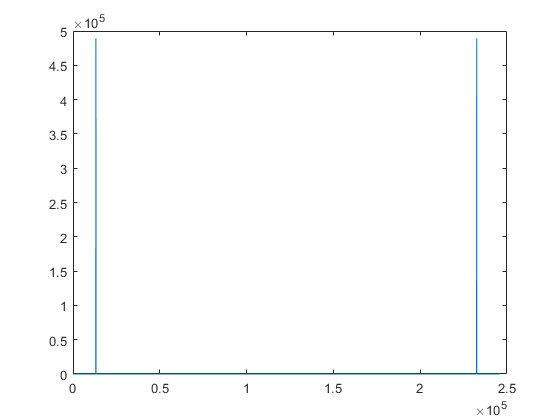

plot(abs(fft(a)))

b = load('handel')

b = struct with fields:
     y: [73113×1 double]
    Fs: 8192


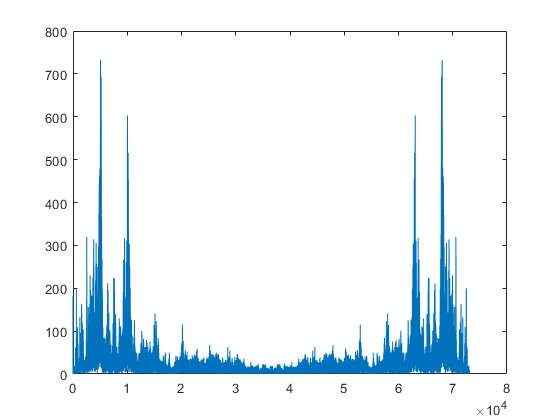

plot(abs(fft(b.y)))

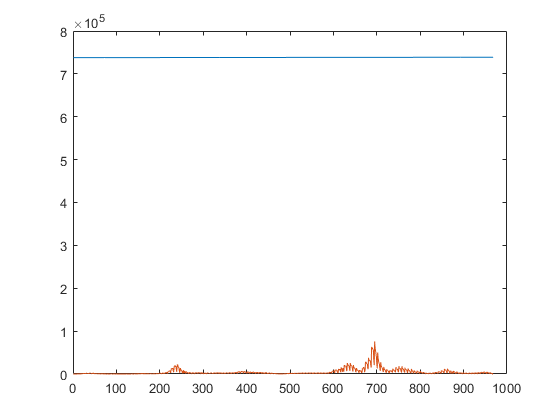

c = csvread("covid19(1).csv");
plot(c)

Sampling:

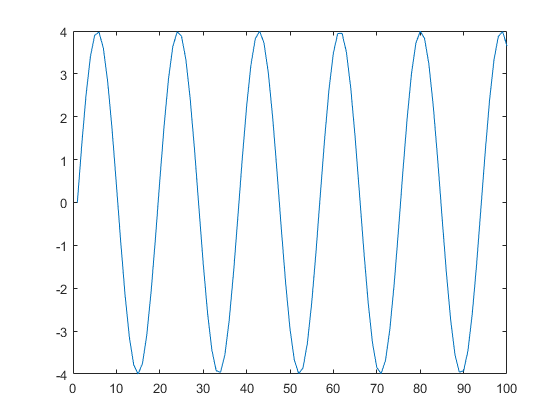

plot(a(1:100))

Discrete tijdsdomein eerste 100 samples:

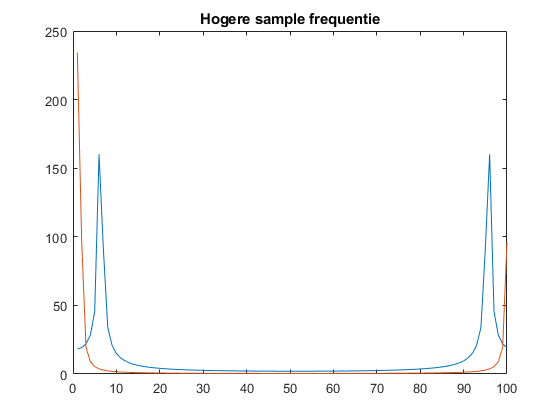

plot(abs(fft(a(1:100))))
title('Hogere sample frequentie')
hold on

fs = fs * 10;
Ts = 1/fs;
t = (0:Ts:30);
a = r * sin(2 * pi * f * t);
plot(abs(fft(a(1:100))))
hold off

We horen een zeer storend geluid...

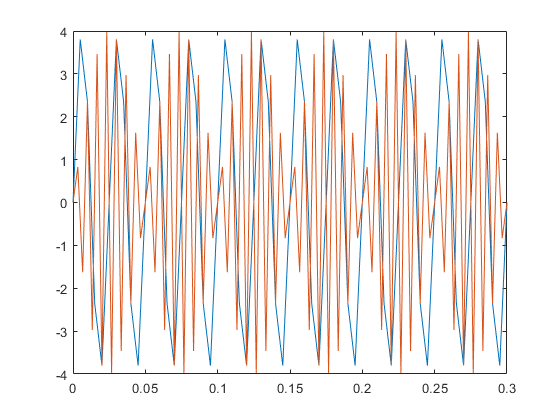

fs = 200;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

hold on

fs = 300;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

hold off

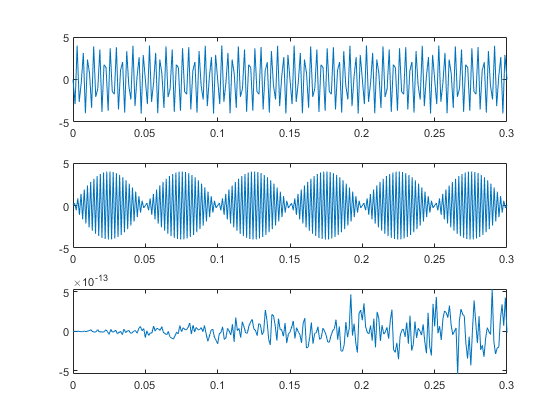

subplot(3, 1, 1);

fs = 700;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

subplot(3, 1, 2);
fs = 900;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

subplot(3, 1, 3);
fs = 880;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

Wanneer we deze samplefrequentie te laag nemen (onder de 2x de frequentie), dan is het stelsel van Nyquist niet tevreden en treed er aliasing op.

wanneer de sample frequentie exact gelijk is aan 2x de frequentie, dan krijgen we een lijn die (praktisch) nul is. Deze toont anders aan omdat de schaal zeer klein is en dit is denk ik doordat er enkele afrondingen gebeuren